# Expand Example 2.11:

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Natural response of the exponential smoother:

$y_{h}[n]=c\,(1-\alpha)^n$  for  $n\ge 0$                    (2.40)

Let the initial output value be


$$y_{h}[-1]=A$$


Then

 
$$c\,(1-\alpha)^{-1}=A
\quad\quad\Longrightarrow\quad\quad
c=A\,(1-\alpha)$$


and


$$y_{h}[n]=A\,(1-\alpha)^{n+1}$$


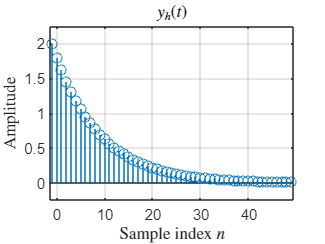

A =     2; % Initial value for n=-1
alpha = 0.1;
%
n = [-1:49];   % Vector of sample indices
% Compute and graph the natural response
yh = A*(1-alpha).^(n+1);
stem(n,yh); grid;
axis([-1.5,49.5,-0.25,2.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('Sample index $n$');
ylabel('Amplitude');
title('$y_{h}(t)$');

set(0,'defaultTextInterpreter','tex');